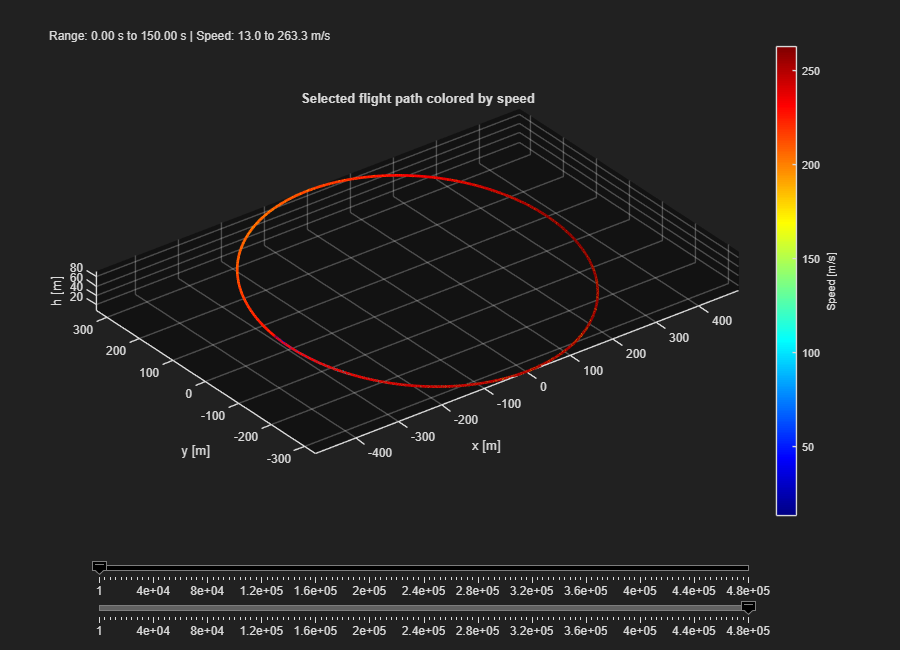

x = out.logsout.get("x").Values.Data;
y = out.logsout.get("y").Values.Data;
z = out.logsout.get("h").Values.Data;
v = out.logsout.get("v").Values.Data;
t = out.logsout.get("v").Values.Time;

N = length(t);

fig = uifigure('Name','Dynamic Soaring Range Viewer','Position',[100 100 900 650]);
ax = uiaxes(fig,'Position',[50 130 780 480]);

sldStart = uislider(fig,'Position',[100 80 650 3],'Limits',[1 N],'Value',1);
sldEnd   = uislider(fig,'Position',[100 40 650 3],'Limits',[1 N],'Value',N);

lbl = uilabel(fig,'Position',[50 600 800 30]);

sldStart.ValueChangingFcn = @(src,event) updatePlot(ax,lbl,round(event.Value),round(sldEnd.Value),x,y,z,v,t);
sldEnd.ValueChangingFcn   = @(src,event) updatePlot(ax,lbl,round(sldStart.Value),round(event.Value),x,y,z,v,t);

updatePlot(ax,lbl,1,N,x,y,z,v,t);


function updatePlot(ax,lbl,k1,k2,x,y,z,v,t)

    if k1 > k2
        tmp = k1;
        k1 = k2;
        k2 = tmp;
    end

    idx = k1:k2;

    cla(ax)

    surface(ax, ...
        [x(idx) x(idx)], ...
        [y(idx) y(idx)], ...
        [z(idx) z(idx)], ...
        [v(idx) v(idx)], ...
        'FaceColor','none', ...
        'EdgeColor','interp', ...
        'LineWidth',2);

    colormap(ax,jet)
    cb = colorbar(ax);
    cb.Label.String = 'Speed [m/s]';

    caxis(ax,[min(v(idx)) max(v(idx))])

    grid(ax,'on')
    axis(ax,'equal')
    view(ax,3)

    xlabel(ax,'x [m]')
    ylabel(ax,'y [m]')
    zlabel(ax,'h [m]')

    title(ax,'Selected flight path colored by speed')

    lbl.Text = sprintf( ...
        'Range: %.2f s to %.2f s | Speed: %.1f to %.1f m/s', ...
        t(k1), t(k2), min(v(idx)), max(v(idx)));

end